load handel.mat
filename = 'handel.flac'; 
min(y)

ans = -0.8000

mean(y)

ans = 0.0025

var(y)

ans = 0.0385

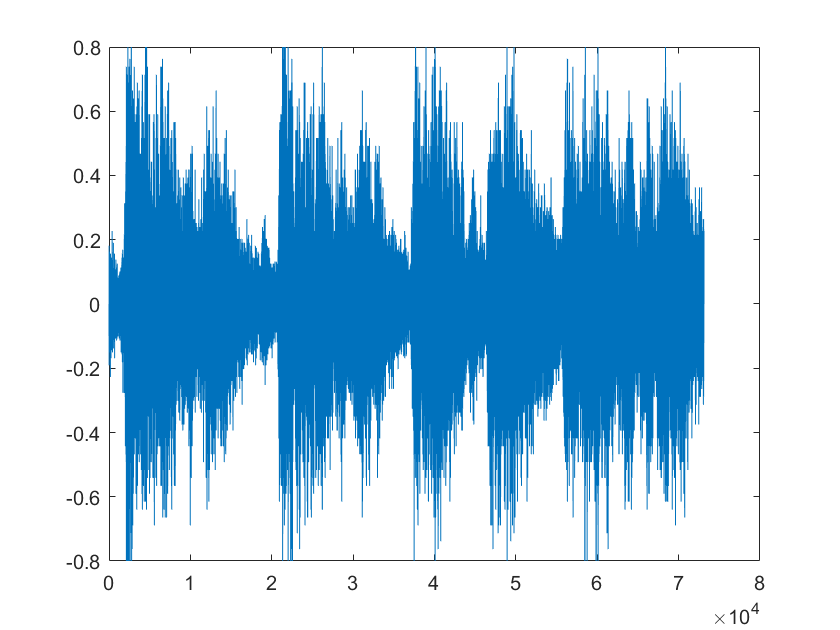

plot(y)



audiowrite(filename,y,Fs,'BitsPerSample',24,'Comment','This is my new audio file.'); 

info = audioinfo(filename) 

info = struct with fields:
             Filename: 'C:\Users\Alexi\Documents\Alexis Iteso\9no semestre\Sistemas de Comunicaciones Digitales\handel.flac'
    CompressionMethod: 'FLAC'
          NumChannels: 1
           SampleRate: 8192
         TotalSamples: 73113
             Duration: 8.9249
                Title: []
              Comment: 'This is my new audio file.'
               Artist: []
        BitsPerSample: 24



info.TotalSamples/info.SampleRate

ans = 8.9249


sound(y, Fs)    % Sin normalizar
soundsc(y, Fs)  % Normalizadopor hardware entre 1 y -1 volts


%Únicamente2 segundos
samples =[1,2*Fs];    % [start,finish].
clear y Fs
[y,Fs]=audioread(filename,samples)

y =          0
   -0.0062
   -0.0750
   -0.0312
    0.0062
    0.0381
    0.0189
   -0.0250
   -0.0312
   -0.0750


Fs = 8192

%[y,Fs]=audioread(filename,samples,'native');  %En enterosla y


load handel.mat % Recuperar la señal “y” en valores [-1 1]
k=8;                                 % Cantidad de bits para Cuantizar
%% Cuantizar a entero y expresión en binario
swing = (2^k-1)/2;                   % Señal simétrica
xq_int = round(y*swing+swing);       % Convertir a entero en [0 2^b-1]
xq_bin = de2bi(xq_int,k,'left-msb'); % Convertir entero a binario
xq_bin(100,:)

ans =      1     0     0     0     1     0     1     0


max(y)

ans = 0.8000


xq_bin = decimalToBinaryVector(xq_int,k,'MSBFirst'); %Opción 1
xq_bin = decimalToBinaryVector(xq_int,k,'LSBFirst'); %Opción 2


